msg = 10^7;
msg_symbols = randi([0 1], msg/log2(4), log2(4));

% A)  Calculating BER 
output = OFDM(msg_symbols, 1024, 400, 20, 3, "AWGN", "eqz_off");
BER_A = Calculate_Error(output, msg_symbols);
display(BER_A);

BER_A = 0.4984

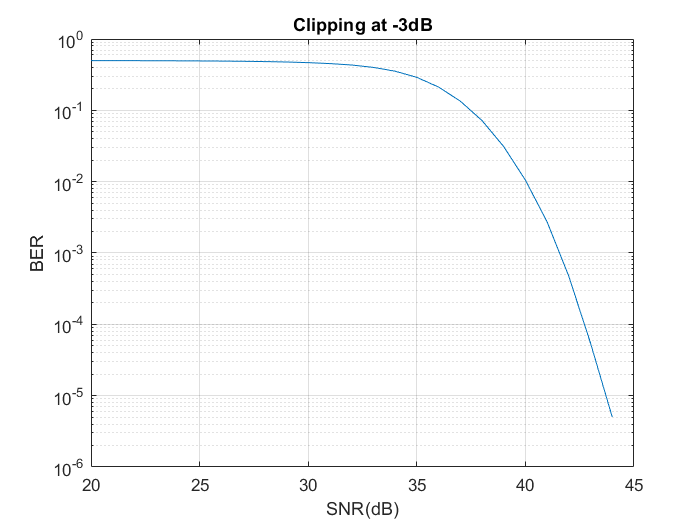

% B)  BER over SNR
BER_B = zeros(1,31);
for i = 0:30
    out = OFDM(msg_symbols, 1024, 400, 20+i, 3, "AWGN", "eqz_off");
    BER_B(i+1) = Calculate_Error(out, msg_symbols);
end

% Plotting Results:
figure
semilogy(20:50,BER_B);
grid on
xlabel("SNR(dB)")
ylabel('BER')
title("Clipping at -3dB")

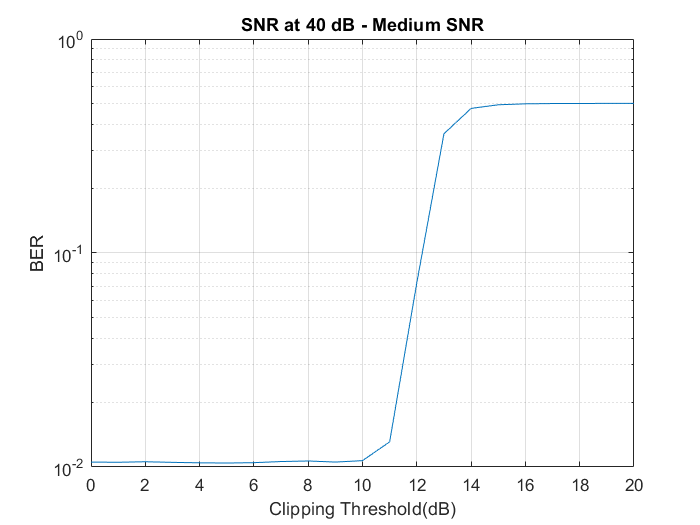

% C) BER over Clipping threshold with SNR = 40 (medium)

BER_C = zeros(1,21);
for i = 0:20
    out = OFDM(msg_symbols, 1024, 400, 40, i, "AWGN", "eqz_off");
    BER_C(i+1) = Calculate_Error(out, msg_symbols);
end

% Plotting Results:
figure
semilogy(0:20,BER_C);
grid on
xlabel("Clipping Threshold(dB)")
ylabel('BER')
title("SNR at 40 dB - Medium SNR")

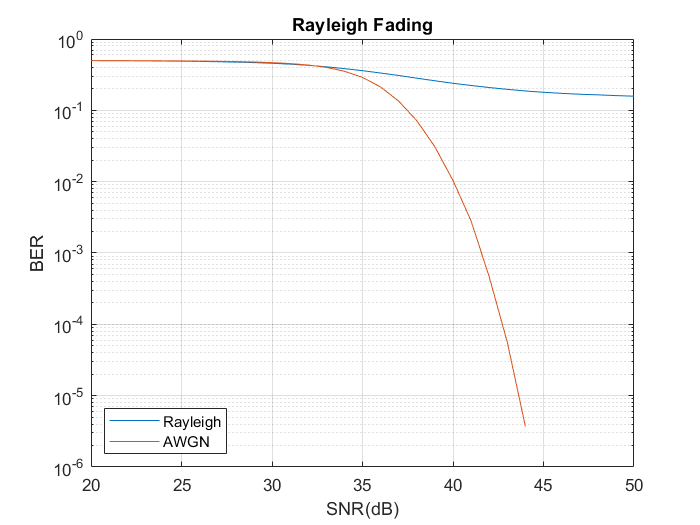

% D) BER over SNR with rayleigh fading channel

BER_D = zeros(1,31);
for i = 0:30
    out = OFDM(msg_symbols, 1024, 400, 20+i, 3,  "ray", "eqz_off");
    BER_D(i+1) = Calculate_Error(out, msg_symbols);
end

% Plotting Results:
figure
semilogy(20:50, BER_D);
hold on
semilogy(20:50, BER_B);
legend('Rayleigh','AWGN', "Location", "southwest")
grid on
xlabel("SNR(dB)")
ylabel('BER')
title("Rayleigh Fading")

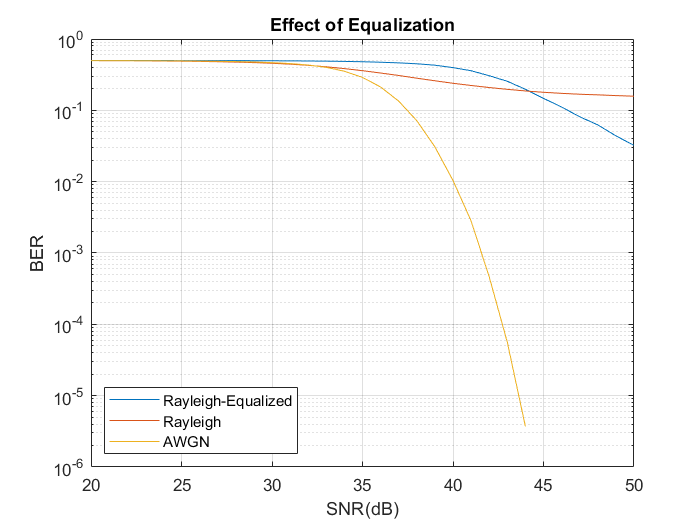

% E) BER over SNR with rayleigh channel and receiver equalizer (MMSE)

BER_E = zeros(1,31);
for i = 0:30
    out = OFDM(msg_symbols, 1024, 400, 20+i, 3, "ray", "eqz_on");
    BER_E(i+1) = Calculate_Error(out, msg_symbols);
end

% Plotting Results:
figure
semilogy(20:50, BER_E);
hold on
semilogy(20:50,BER_D);
hold on
semilogy(20:50, BER_B);
legend('Rayleigh-Equalized','Rayleigh', 'AWGN', 'Location', 'southwest')
grid on
xlabel("SNR(dB)")
ylabel('BER')
title("Effect of Equalization")

% F) Synchronization via Pilot Correlation (Bonus)

[BER_Bonus, corr, corr_indices] = OFDM(msg_symbols, 1024, 400, 20, 3, "AWGN", "eqz_off");
display(BER_Bonus); 

BER_Bonus =      1     0
     0     0
     0     1
     1     0
     1     0
     1     1
     0     0
     0     0
     1     0
     0     1



figure
s = semilogy(corr_indices, corr)

s =   Line with properties:

> In matlab.internal.editor/OutputPackager/isolatedDisplaying
  In matlab.internal.editor/OutputPackager/getStringFromVar
  In matlab.internal.editor/OutputPackager/getTruncatedStringFromVar
  In matlab.internal.editor/OutputPackager/packageVarOther
  In matlab.internal.editor/OutputPackager/packageVar
  In matlab.internal.editor/OutputPackager/packageOneOutput
  In matlab.internal.editor/OutputPackager/packageEachOutput
  In matlab.internal.editor/OutputPackager/packageOutputs
  In matlab.internal.editor/EvaluationOutputsService/outputStreamEvent
  In matlab.internal.editor.EvaluationOutputsService>@(src,ev)EvaluationOutputsService.outputStreamEvent(src,ev,editorId,requestId,filePath)
  In matlab.internal.editor/OutputsManager/streamOutputsCallback
  In matlab.internal.editor.OutputsManager>@(varargin)obj.streamOutputsCallback(vararg

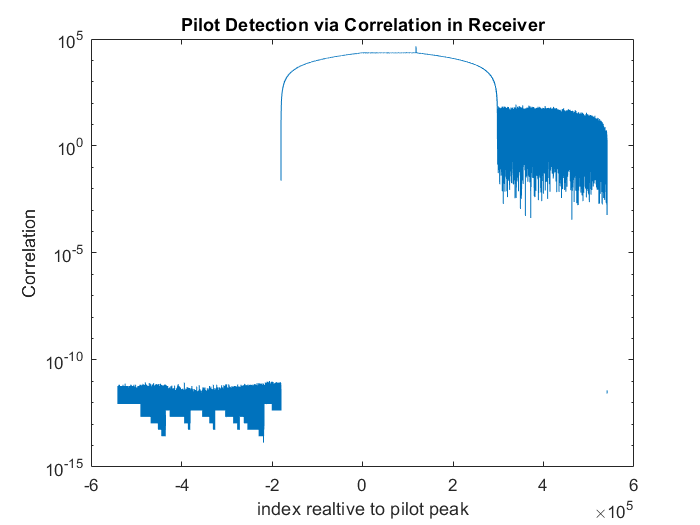

xlabel("index realtive to pilot peak");
ylabel('Correlation');
title("Pilot Detection via Correlation in Receiver");

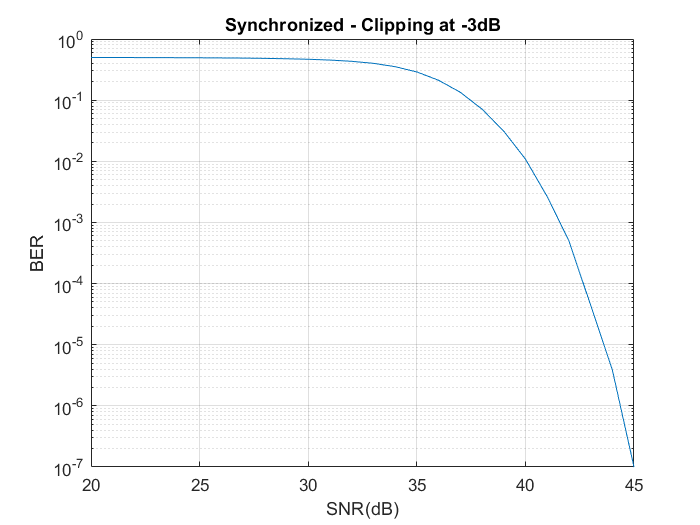



BER_F = zeros(1,31);
for i = 0:30
    out = OFDM(msg_symbols, 1024, 400, 20+i, 3, "AWGN", "eqz_off");
    BER_F(i+1) = Calculate_Error(out, msg_symbols);
end

% Plotting Results:
figure
semilogy(20:50,BER_F);
grid on
xlabel("SNR(dB)")
ylabel('BER')
title("Synchronized - Clipping at -3dB")